load uspsDigits.mat

%Find all indexes.
randImgIndex = randi(2007)

randImgIndex = 1098

Zero = find(trainAns==0);
One = find(trainAns==1);
Two = find(trainAns==2);
Three = find(trainAns==3);
Four = find(trainAns==4);
Five = find(trainAns==5);
Six = find(trainAns==6);
Seven = find(trainAns==7);
Eight = find(trainAns==8);
Nine = find(trainAns==9);
% dimension
d = 8;

%Go thru 0:9 reshape to 256, get underrum och basvektor
%Check distance to underrum -> save the assumed digit and compare with
%answer sheet. Check success rate et cetera.
%Display all sevens that were incorrect demonstrate why and some example of
%sevens that were correct and why.

A0 = zeros(256, length(Zero)); % reshaped zeroes.
for i = 1:size(Zero)   
     iZeros = trainDigits(:,:,Zero(i)); % take each zero from Zero[]
     A = reshape(iZeros, [256,1]); % reshape 16x16 to 256
     A0(:,i) = A; % add the reshaped Zero to Zero matrix                                       
end

% Underrum för nollor
[U0, S0, V0] = svd(A0);
% Basvektorer, de d första vektorerna i U0
B0 = U0(:,1:d);

A1 = zeros(256, length(One)); % reshaped zeroes.
for i = 1:size(One)   
     iOne = trainDigits(:,:,One(i)); % take each zero from Zero[]
     A = reshape(iOne, [256,1]); % reshape 16x16 to 256
     A1(:,i) = A; % add the reshaped Zero to Zero matrix                                       
end

% Underrum för nollor
[U1, S1, V1] = svd(A1);
% Basvektorer, de d första vektorerna i U1
B1 = U1(:,1:d);

A2 = zeros(256, length(Two)); % reshaped zeroes.
for i = 1:size(Two)   
     iTwo = trainDigits(:,:,Two(i)); % take each zero from Zero[]
     A = reshape(iTwo, [256,1]); % reshape 16x16 to 256
     A2(:,i) = A; % add the reshaped Zero to Zero matrix                                       
end

% Underrum för nollor
[U2, S2, V2] = svd(A2);
% Basvektorer, de d första vektorerna i U1
B2 = U2(:,1:d);

A3 = zeros(256, length(Three)); % reshaped zeroes.
for i = 1:size(Three)   
     iThree = trainDigits(:,:,Three(i)); % take each zero from Zero[]
     A = reshape(iThree, [256,1]); % reshape 16x16 to 256
     A3(:,i) = A; % add the reshaped Zero to Zero matrix                                       
end

% Underrum för nollor
[U3, S3, V3] = svd(A3);
% Basvektorer, de d första vektorerna i U1
B3 = U3(:,1:d);

A4 = zeros(256, length(Four)); % reshaped zeroes.
for i = 1:size(Four)   
     iFour = trainDigits(:,:,Four(i)); % take each zero from Zero[]
     A = reshape(iFour, [256,1]); % reshape 16x16 to 256
     A4(:,i) = A; % add the reshaped Zero to Zero matrix                                       
end

% Underrum för nollor
[U4, S4, V4] = svd(A4);
% Basvektorer, de d första vektorerna i U1
B4 = U4(:,1:d);

A5 = zeros(256, length(Five)); % reshaped zeroes.
for i = 1:size(Five)   
     iFive = trainDigits(:,:,Five(i)); % take each zero from Zero[]
     A = reshape(iFive, [256,1]); % reshape 16x16 to 256
     A5(:,i) = A; % add the reshaped Zero to Zero matrix                                       
end

% Underrum för nollor
[U5, S5, V5] = svd(A5);
% Basvektorer, de d första vektorerna i U1
B5 = U5(:,1:d);

A6 = zeros(256, length(Six)); % reshaped zeroes.
for i = 1:size(Six)   
     iSix = trainDigits(:,:,Six(i)); % take each zero from Zero[]
     A = reshape(iSix, [256,1]); % reshape 16x16 to 256
     A6(:,i) = A; % add the reshaped Zero to Zero matrix                                       
end

% Underrum för nollor
[U6, S6, V6] = svd(A6);
% Basvektorer, de d första vektorerna i U1
B6 = U6(:,1:d);

A7 = zeros(256, length(Seven)); % reshaped zeroes.
for i = 1:size(Seven)   
     iSeven = trainDigits(:,:,Seven(i)); % take each zero from Zero[]
     A = reshape(iSeven, [256,1]); % reshape 16x16 to 256
     A7(:,i) = A; % add the reshaped Zero to Zero matrix                                       
end

% Underrum för nollor
[U7, S7, V7] = svd(A7);
% Basvektorer, de d första vektorerna i U1
B7 = U7(:,1:d);

A8 = zeros(256, length(Eight)); % reshaped zeroes.
for i = 1:size(Eight)   
     iEight = trainDigits(:,:,Eight(i)); % take each zero from Zero[]
     A = reshape(iEight, [256,1]); % reshape 16x16 to 256
     A8(:,i) = A; % add the reshaped Zero to Zero matrix                                       
end

% Underrum för nollor
[U8, S8, V8] = svd(A8);
% Basvektorer, de d första vektorerna i U1
B8 = U8(:,1:d);

A9 = zeros(256, length(Nine)); % reshaped zeroes.
for i = 1:size(Nine)   
     iNine = trainDigits(:,:,Nine(i)); % take each zero from Zero[]
     A = reshape(iNine, [256,1]); % reshape 16x16 to 256
     A9(:,i) = A; % add the reshaped Zero to Zero matrix                                       
end

% Underrum för nollor
[U9, S9, V9] = svd(A9);
% Basvektorer, de d första vektorerna i U1
B9 = U9(:,1:d);

R = zeros(2007,1);
for i = 1:length(R)

   x = reshape(testDigits(:,:,i), [256,1]);

    x0 = B0*(B0')*x;
        reshapedx0 = reshape(x0, [16,16,1]);

    x1 = B1*(B1')*x;
        reshapedx1 = reshape(x1, [16,16,1]);

    x2 = B2*(B2')*x;
        reshapedx2 = reshape(x2, [16,16,1]);

    x3 = B3*(B3')*x;
        reshapedx3 = reshape(x3, [16,16,1]);

    x4 = B4*(B4')*x;
        reshapedx4 = reshape(x4, [16,16,1]);

    x5 = B5*(B5')*x;
        reshapedx5 = reshape(x5, [16,16,1]);

    x6 = B6*(B6')*x;
        reshapedx6 = reshape(x6, [16,16,1]);

    x7 = B7*(B7')*x;
        reshapedx7 = reshape(x7, [16,16,1]);

    x8 = B8*(B8')*x;
        reshapedx8 = reshape(x8, [16,16,1]);

    x9 = B9*(B9')*x;
        reshapedx9 = reshape(x9, [16,16,1]);
  
    % Avstånd till underrummet 
    %r0 = x - x0;    n0 = sqrt(sum(r0.^2));
    n0 =  norm(x-x0, 2);
    min_dis = n0;
    n = 0;

    %r1 = x - x1;    n1 = sqrt(sum(r1.^2));
    n1 =  norm(x-x1, 2);
     if min_dis > n1 
        min_dis = n1;
        n = 1; 
     end

    %r2 = x - x2;    n2 = sqrt(sum(r2.^2));
    n2 =  norm(x-x2, 2);
     if min_dis > n2 
        min_dis = n2;
        n = 2;
     end

    %r3 = x - x3;    n3 = sqrt(sum(r3.^2));
    n3 =  norm(x-x3, 2);
     if min_dis > n3 
        min_dis = n3;
        n = 3;
     end

    %r4 = x - x4;    n4 = sqrt(sum(r4.^2));
    n4 =  norm(x-x4, 2);
     if min_dis > n4
        min_dis = n4;
        n = 4;
     end
    
    %r5 = x - x5;    n5 = sqrt(sum(r5.^2));
    n5 =  norm(x-x5, 2);
     if min_dis > n5 
        min_dis = n5;
        n = 5;
     end

    %r6 = x - x6;    n6 = sqrt(sum(r6.^2));
    n6 =  norm(x-x6, 2);
     if min_dis > n6
        min_dis = n6;
        n = 6;
     end

    %r7 = x - x7;    n7 = sqrt(sum(r7.^2));
    n7 =  norm(x-x7, 2);
     if min_dis > n7 
        min_dis = n7;
        n = 7;
     end

    %r8 = x - x8;    n8 = sqrt(sum(r8.^2));
    n8 =  norm(x-x8, 2);
     if min_dis > n8
        min_dis = n8;
        n = 8;
     end 

    %r9 = x - x9;    n9 = sqrt(sum(r9.^2)); 
    n9 =  norm(x-x9, 2);
     if min_dis > n9 
        min_dis = n9;
        n = 9;
     end 

    R(i) = n;
end

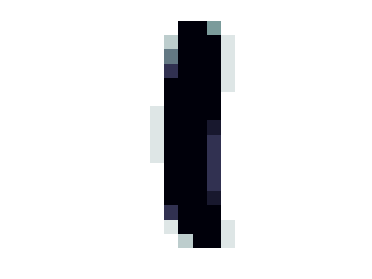

inCorr = 0;

inCorrectSevens = zeros(9);

wZero = 0; wOne = 0; wTwo = 0; wThree = 0; wFour = 0;
wFive = 0; wSix = 0; wSeven = 0; wEight = 0; wNine = 0;

 for j = 1:length(R)
     % Antal som inte matchar facit
    if R(j) ~= testAns(j,:)
        inCorr = inCorr + 1;

        % Räkna hur många fel per siffra
        if testAns(j,:) == 0
            wZero = wZero + 1;
        end

        if testAns(j) == 1
            wOne = wOne + 1;
        end

        if testAns(j) == 2
            wTwo = wTwo + 1;
        end

        if testAns(j) == 3
            wThree = wThree + 1;
        end

        if testAns(j) == 4
            wFour = wFour + 1;
        end

        if testAns(j) == 5
            wFive = wFive + 1;
        end

        if testAns(j) == 6
            wSix = wSix + 1;
        end

        if testAns(j) == 7
            wSeven = wSeven + 1;
        end

        if testAns(j) == 8
            wEight = wEight + 1;
        end

        if testAns(j) == 9
            wNine = wNine + 1;
        end
    end
 end

 ima(reshapedx0)
 ima(reshapedx1)
 ima(reshapedx2)  

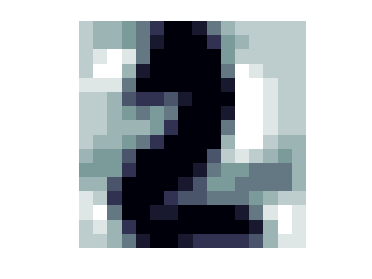

 ima(reshapedx3)

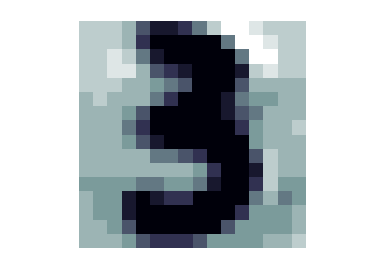

  ima(reshapedx4)

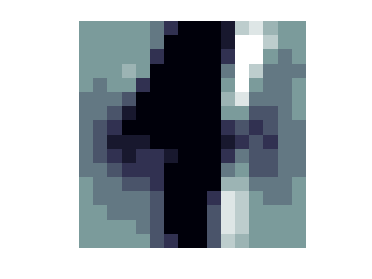

   ima(reshapedx5)

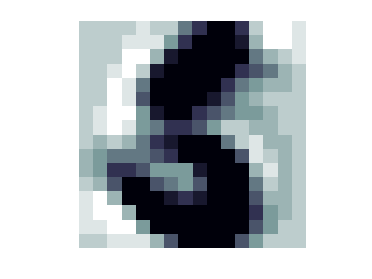

    ima(reshapedx6)

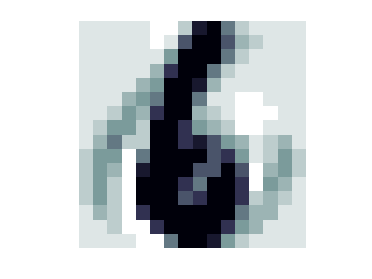

     ima(reshapedx7)

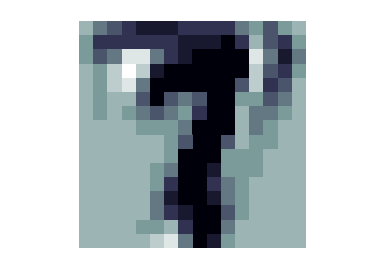

      ima(reshapedx8)

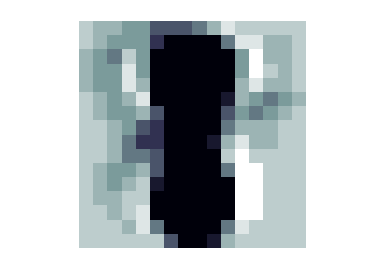

       ima(reshapedx9)

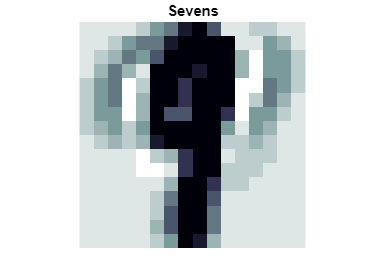


title('Sevens')
ima(reshapedx7)

% for i = inCorrectSevens
%     ima(testDigits(:,:,i))
% end

testZero = find(trainAns==0);
testOne = find(trainAns==1);
testTwo = find(trainAns==2);
testThree = find(trainAns==3);
testFour = find(trainAns==4);
testFive = find(trainAns==5);
testSix = find(trainAns==6);
testSeven = find(trainAns==7);
testEight = find(trainAns==8);
testNine = find(trainAns==9);

Correct = length(R) - inCorr;
CorrectZero = length(testZero) - wZero;
CorrectOne = length(testOne) - wOne;
CorrectTwo = length(testTwo) - wTwo;
CorrectThree = length(testThree) - wThree;
CorrectFour = length(testFour) - wFour;
CorrectFive = length(testFive) - wFive;
CorrectSix = length(testSix) - wSix;
CorrectSeven = length(testSeven) - wSeven;
CorrectEight = length(testEight) - wEight;
CorrectNine = length(testNine) - wNine;

success_Rate = Correct/length(R) * 100;
success_Rate_Zeros = CorrectZero/length(testZero)* 100;
success_Rate_Ones = CorrectOne/length(testOne)* 100;
success_Rate_Twos = CorrectTwo/length(testTwo)* 100;
success_Rate_Threes = CorrectThree/length(testThree)* 100;
success_Rate_Fours = CorrectFour/length(testFour)* 100;
success_Rate_Fives = CorrectFive/length(testFive)* 100;
success_Rate_Sixes = CorrectSix/length(testSix)* 100;
success_Rate_Sevens = CorrectSeven/length(testSeven)* 100;
success_Rate_Eights = CorrectEight/length(testEight)* 100;
success_Rate_Nines = CorrectNine/length(testNine)* 100;

Class = {'Total';'Zero';'One';'Two';'Three';'Four';'Five';'Six';'Seven';'Eight';'Nine'};
Percentage = [success_Rate;success_Rate_Zeros;success_Rate_Ones;success_Rate_Twos;success_Rate_Threes;success_Rate_Fours;
success_Rate_Fives;success_Rate_Sixes;success_Rate_Sevens;success_Rate_Eights;success_Rate_Nines;];

T = table(Class, Percentage)

T = 11×2 table
      Class      Percentage
    _________    __________

    {'Total'}      93.274  
    {'Zero' }       99.33  
    {'One'  }      99.502  
    {'Two'  }      96.717  
    {'Three'}       96.96  
    {'Four' }      96.626  
    {'Five' }      97.842  
    {'Six'  }      99.096  
    {'Seven'}      98.605  
    {'Eight'}      96.863  
    {'Nine' }      98.137  
